Nach einer Entscheidung des Chefs wird das Instrument von einer anderen Kollegin auf einer anderen Hardwareplattform mit einer Samplerate von 48 kHz umgesetzt und durch digitale Umsetzungen einiger anderer von der Band verwendeter Geräte ergänzt. Bei der Entwicklung des abschließenden Filters für den so wichtigen „charakteristischen Klang” der Band wird jedoch für eine bessere Umsetzung die Samplerate auf 96 kHz verdoppelt. Sie sollen eine erste, simple Testimplementation davon beitragen.

Diese Testimplementation soll für einen Abschnitt des Tonsignals (das könnte zum Beispiel einer der gespielten Töne sein) die DFT des Signals berechnen, im Frequenzbereich durch taktisches Ergänzen mit Nullen die Anzahl der Samples verdoppeln (wir gehen für eine einfache Testimplementation voneinem fixen Faktor 2 aus) und anschließend das Signal in den Zeitbereich zurück umwandeln.

Plotten Sie um die Funktion zu prüfen und zu zeigen beide Signale im Vergleich, wählen Sie dazu eine beliebige Tastennummer und eine der bisherigen Oberton-Konfigurationen als Demonstration und begrenzen Sie den Plot auf ein sinnvolles Zeitintervall. Ist diese Methode für ein live gespieltes Instrument praxistauglich?

clear;
global Fs lengthOf1 m c_m;
Fs = 48000; % Samplerate
lengthOf1 = 0.8; % Dauer einer "ganzen Note" in Sekunden
m = [1 2 3 4 6 8 10 12 14 16 18 20 24]; % Vektor der implementierten Obertöne
c_m = [0 0.7092 0 1 0.2530 0.1794 0.0903 0 0 0 0.1 0.05 0.1];
mainVolume = 0.01;

y = makeTone(44, 1, 0.1);

Y = fft(y);
Yi = [Y(1:end/2) zeros(1, length(Y)+1) Y(end/2+1:end)];

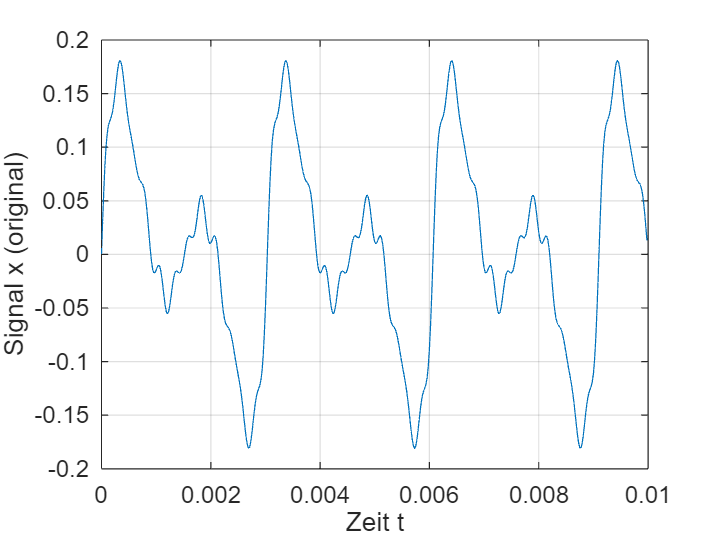


x = ifft(Y);
xi = ifft(Yi);

sound(x,48000);

pause(4);

sound(real(xi), 96000);

t1 = 0: 1/(48000 - 1) :0.01;
t2 = 0: 1/(96000 - 1) :0.01;

plot(t1, real(x(1, 1:length(t1))));
xlabel("Zeit t");
ylabel("Signal x (original)");
grid on;

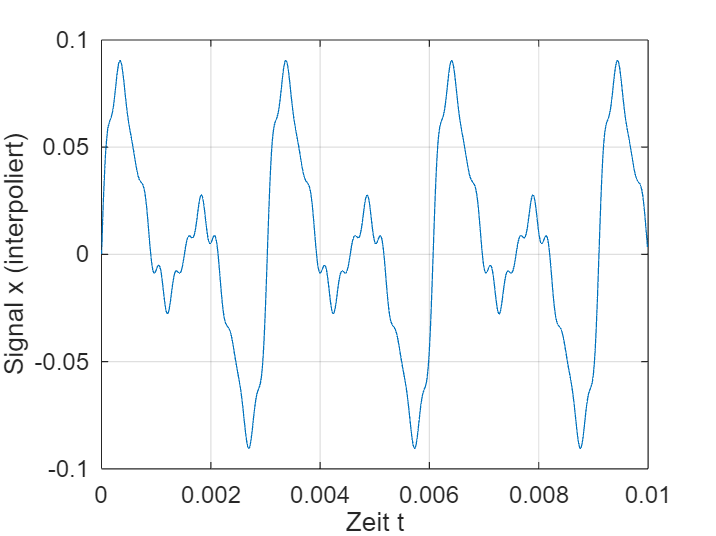

plot(t2, real(xi(1, 1:length(t2))));
xlabel("Zeit t");
ylabel("Signal x (interpoliert)");
grid on;